# Demonstration of imshow

[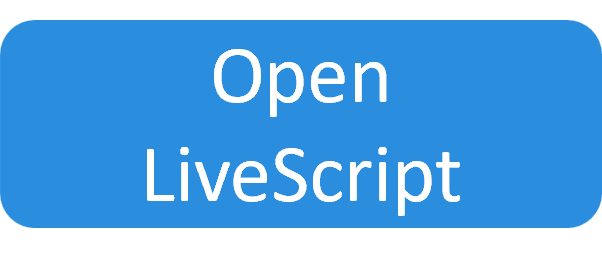](matlab:dxdzds.file='imshow_demo';dxdzds.outFile=fullfile(pwd,dxdzds.file); copyfile(which(['user_' dxdzds.file]),[dxdzds.outFile '.mlx']);open(dxdzds.outFile);clear dxdzds;)

Let's first do a little bit of cleaning.

clearvars
close all
clc

Let's first create an iterative display object

id = iterativeDisplay;

Here are the image generation parameters

nImg = 100;  % Number of images
nx   = 500;  % Nb of x points
ny   = 501;  % Nb of y points

Now we generate X-Y matrices using meshgrid 

[X,Y]=meshgrid(linspace(-1,1,nx),linspace(-1,1,ny));
P = linspace(1,5,nImg); 

Then, we arey going to create  an animated image and plot it using `id.imshow`.

You  an now benefits of a smooth and fast display of the computed image without programming yourself the 

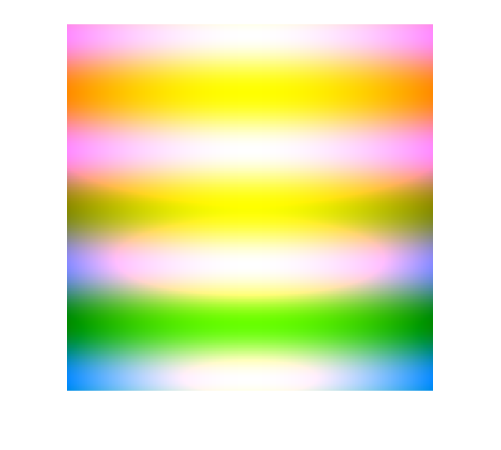

for i=1:nImg
    p=P(i);
    R=(cos(X*5/p).*sin(Y*p)).^2+cos(X)-sin(Y);
    G=cos(X*5/p);
    B=sin(Y*p).^2;
    Z=cat(3,R,G,B);
    % Display
    id.newIteration;
    id.figure;
    id.imshow(Z);
    drawnow;
end